%%number 2%%
%%%Stuart McDonald James Brown Sam Austin
syms s u
%%energy function%%
W=  1+(1+0.65.*s-1.2.*s.^2-0.4.*s.^3+0.35.*s.^4).*cos(u)...
    +(1.4.*s-0.4.*s.^2-1.5.*s.^3-0.35.*s.^4).*sin(u)

$$W = \cos\left(u\right)\,\left(\frac{7\,s^{4}}{20}-\frac{2\,s^{3}}{5}-\frac{6\,s^{2}}{5}+\frac{13\,s}{20}+1\right)-\sin\left(u\right)\,\left(\frac{7\,s^{4}}{20}+\frac{3\,s^{3}}{2}+\frac{2\,s^{2}}{5}-\frac{7\,s}{5}\right)+1$$

%%create gradient
fun=[diff(W,s)==0 ;diff(W,u)==0]

$$fun = \begin{array}{l} \left(\begin{array}{c} -\cos\left(u\right)\,\left(-\sigma_{2}+\sigma_{3}+\frac{12\,s}{5}-\frac{13}{20}\right)-\sin\left(u\right)\,\left(\sigma_{2}+\frac{9\,s^{2}}{2}+\frac{4\,s}{5}-\frac{7}{5}\right)=0\\ -\sin\left(u\right)\,\left(\sigma_{1}-\frac{2\,s^{3}}{5}-\sigma_{3}+\frac{13\,s}{20}+1\right)-\cos\left(u\right)\,\left(\sigma_{1}+\frac{3\,s^{3}}{2}+\frac{2\,s^{2}}{5}-\frac{7\,s}{5}\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,s^{4}}{20}\\ \sigma_{2}=\frac{7\,s^{3}}{5}\\ \sigma_{3}=\frac{6\,s^{2}}{5} \end{array}$$

%%find critical values
sol1=vpasolve(fun)

sol1 = struct with fields:
    s: [1×1 sym]
    u: [1×1 sym]


sol2=vpasolve(fun,[u s], [-0.72 -0.41])

sol2 = struct with fields:
    u: [0×1 sym]
    s: [0×1 sym]


sol2.s

 
ans =
 
Empty sym: 0-by-1
 


sol2.u

 
ans =
 
Empty sym: 0-by-1
 


%%plot surface with critical point
figure1=fsurf(W,[-0.4 0.4 -pi/2 pi/2],'MeshDensity',100)

figure1 =   FunctionSurface with properties:

     Function: [1×1 sym]
       XRange: [-0.4000 0.4000]
       YRange: [-1.5708 1.5708]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    FaceColor: 'interp'

  Show all properties


hold on
x=sol1.s

$$x = 0.32402033494385365846509316769633$$

y=sol1.u

$$y = 0.32045607931360856519330337101094$$

%%calculate W at critical point
z = subs(W,s,sol1.s)

$$z = 1.0748767079709905813432426431702\,\cos\left(u\right)+0.35674690068674380699939104224748\,\sin\left(u\right)+1$$

z = subs(z,u,sol1.u)

$$z = 2.1325318046254381531303157878129$$

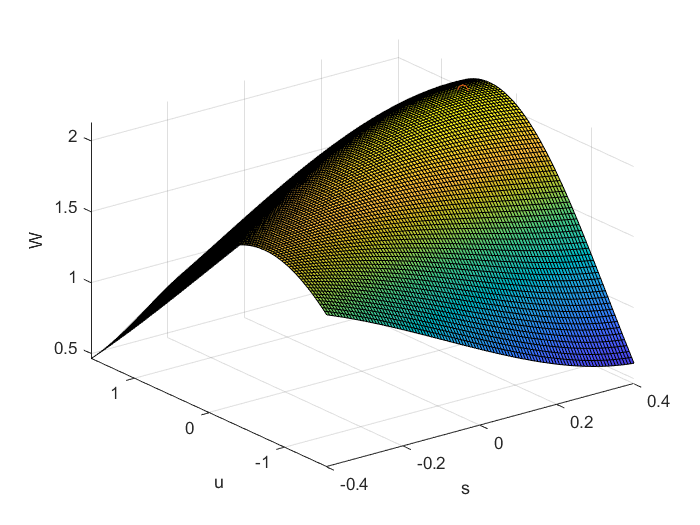

plot3(x,y,z,'o')
xlabel('s')
ylabel('u')
zlabel('W')
hold off

%%create contour with critical point
figure2=fcontour(W,[-0.4 0.4 -pi/2 pi/2])

figure2 =   FunctionContour with properties:

     Function: [1×1 sym]
       XRange: [-0.4000 0.4000]
       YRange: [-1.5708 1.5708]
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]

  Show all properties


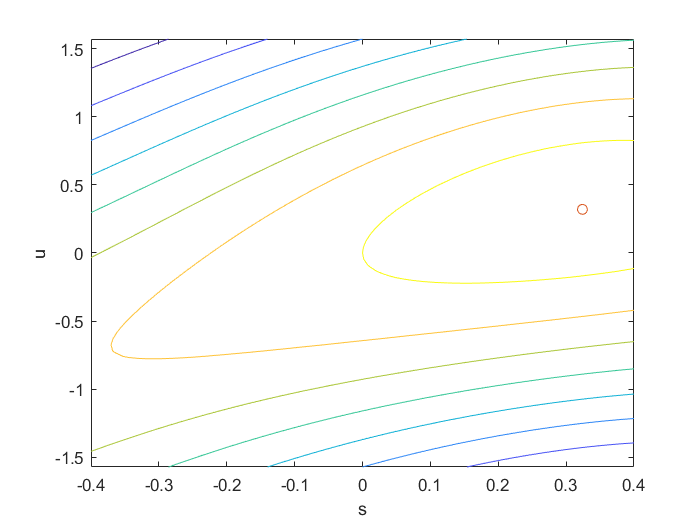

hold on
plot(x,y,'o')
xlabel('s')
ylabel('u')